clear;clc;

定义四连杆参数

link1.l1 = 140;  %134.8
link1.l2 = 40;   %40.45
link1.l3 = 140;  %140
link1.l4 = 50; %50.5

syms theta_2;
link1.theta2 = theta_2; % rad

link1.x1=0;
link1.y1=0;
link1.x2=link1.l2*cos(link1.theta2);
link1.y2=link1.l2*sin(link1.theta2);
link1.x4=link1.l1;
link1.y4=0;


求解两个三角形

link1.l5 = sqrt(link1.l1^2+link1.l2^2-2*link1.l1*link1.l2*cos(link1.theta2));
link1.theta25 = atan2(sin(link1.theta2)*link1.l1/link1.l5,(link1.l2^2+link1.l5^2-link1.l1^2)/(2*link1.l2*link1.l5))*sign(link1.theta2);
link1.theta15 = atan2(sin(link1.theta2)*link1.l2/link1.l5,(link1.l1^2+link1.l5^2-link1.l2^2)/(2*link1.l1*link1.l5))*(-sign(link1.theta2));

link1.theta53 = acos((link1.l3^2+link1.l5^2-link1.l4^2)/(2*link1.l3*link1.l5));
link1.theta54 =-acos((link1.l4^2+link1.l5^2-link1.l3^2)/(2*link1.l4*link1.l5));

link1.x3 = link1.l1-link1.l4*cos(link1.theta15+link1.theta54);
link1.y3 = link1.l4*(-sin(link1.theta15+link1.theta54));

link1.theta3 = atan2(link1.y3-link1.y2,link1.x3-link1.x2);


定义第二组四连杆参数

link2.l1=60;          %60.6
link2.l2=link1.l4;
link2.l3=20;        %21.4
link2.l4=60;      %49.5 
link2.l5=35;      %35.4  

link2.theta2=pi+(link1.theta15+link1.theta54);
link2.theta3=link1.theta3;
link2.x1=link1.x4+0;
link2.y1=0;
link2.x2=link2.x1+link2.l2*cos(link2.theta2);
link2.y2=link2.l2*sin(link2.theta2);
link2.x3=link2.x2+link2.l3*cos(link2.theta3);
link2.y3=link2.y2+link2.l3*sin(link2.theta3);
link2.x5=link2.x1+link2.l1;
link2.y5=0;

求解三角形

link2.l6 = sqrt((link2.x5-link2.x3)^2+(link2.y5-link2.y3)^2);
link2.theta16 = atan2(link2.y3,(link2.x5-link2.x3));
link2.theta64 = acos((link2.l5^2+link2.l6^2-link2.l4^2)/(2*link2.l5*link2.l6));

link2.theta5=pi-(link2.theta16+link2.theta64);

link2.x4=link2.x5+link2.l5*cos(link2.theta5);
link2.y4=link2.l5*sin(link2.theta5);

补足小腿

shank.l=200;      %203.1

link2.theta5=pi-(link2.theta16+link2.theta64);
shank.theta = link2.theta5-(140/180*pi);
shank.x = link2.x5+shank.l*cos(shank.theta);
shank.y = shank.l*sin(shank.theta);

画图

% link1
% link2
% shank
% shank.x
% shank.y
shankx_func = matlabFunction(shank.x)

shankx_func = 包含以下值的 function_handle :
    @(theta_2)cos(pi.*(-2.0./9.0)+acos((1.0./sqrt((cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4))).*5.0e+1+((real(cos(theta_2)).*-4.0e+1+imag(sin(theta_2)).*4.0e+1+real(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1-imag(sin(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1+1.4e+2).*2.0e+1)./abs(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e

shanky_func = matlabFunction(shank.y)

shanky_func = 包含以下值的 function_handle :
    @(theta_2)sin(pi.*(-2.0./9.0)+acos((1.0./sqrt((cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4))).*5.0e+1+((real(cos(theta_2)).*-4.0e+1+imag(sin(theta_2)).*4.0e+1+real(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1-imag(sin(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1+1.4e+2).*2.0e+1)./abs(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e

shankL_func = matlabFunction(sqrt(shank.x^2+shank.y^2))

shankL_func = 包含以下值的 function_handle :
    @(theta_2)sqrt((cos(pi.*(-2.0./9.0)+acos((1.0./sqrt((cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4))).*5.0e+1+((real(cos(theta_2)).*-4.0e+1+imag(sin(theta_2)).*4.0e+1+real(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1-imag(sin(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1+1.4e+2).*2.0e+1)./abs(cos(acos((1.0./sqrt(cos(theta_2).

shankBeta1_func = matlabFunction(atan2(shank.x,-shank.y))

shankBeta1_func = 包含以下值的 function_handle :
    @(theta_2)angle(cos(pi.*(-2.0./9.0)+acos((1.0./sqrt((cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4))).*5.0e+1+((real(cos(theta_2)).*-4.0e+1+imag(sin(theta_2)).*4.0e+1+real(cos(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1-imag(sin(acos((1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-4.1e+3))./2.0e+3)-sign(theta_2).*atan2(sin(theta_2).*1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*1.12e+4,-1.0./sqrt(cos(theta_2).*-2.8e+1+5.3e+1).*(cos(theta_2).*1.12e+4-3.92e+4)))).*5.0e+1+1.4e+2).*2.0e+1)./abs(cos(acos((1.0./sqrt(cos(theta

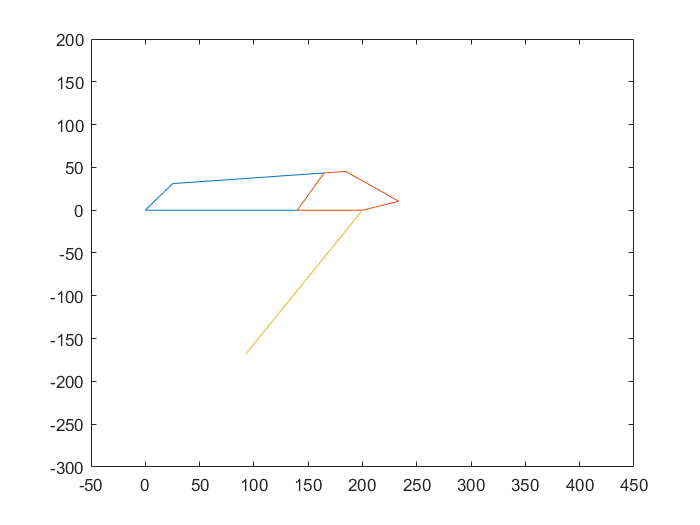

%link1的2，3；link2的2，3，4
link1.x2_func = matlabFunction(link1.x2);
link1.y2_func = matlabFunction(link1.y2);
link1.x3_func = matlabFunction(link1.x3);
link1.y3_func = matlabFunction(link1.y3);

link2.x2_func = matlabFunction(link2.x2);
link2.y2_func = matlabFunction(link2.y2);
link2.x3_func = matlabFunction(link2.x3);
link2.y3_func = matlabFunction(link2.y3);
link2.x4_func = matlabFunction(link2.x4);
link2.y4_func = matlabFunction(link2.y4);

for theta = -0.2:0.01:2.6
    link1.x2 = link1.x2_func(theta);
    link1.y2 = link1.y2_func(theta);
    link1.x3 = link1.x3_func(theta);
    link1.y3 = link1.y3_func(theta);

    link2.x2 = link2.x2_func(theta);
    link2.y2 = link2.y2_func(theta);
    link2.x3 = link2.x3_func(theta);
    link2.y3 = link2.y3_func(theta);
    link2.x4 = link2.x4_func(theta);
    link2.y4 = link2.y4_func(theta);
    
    shank.x = shankx_func(theta);
    shank.y = shanky_func(theta);

    plot([link1.x1,link1.x2,link1.x3,link1.x4,link1.x1],[link1.y1,link1.y2,link1.y3,link1.y4,link1.y1]),hold on
    plot([link2.x1,link2.x2,link2.x3,link2.x4,link2.x5,link2.x1],[link2.y1,link2.y2,link2.y3,link2.y4,link2.y5,link2.y1]),hold on
    plot([link2.x5,shank.x],[link2.y5,shank.y]),hold off
    axis([-50 450,-300 200])
    pause(0.01);
end

% plot([link1.x1,link1.x2,link1.x3,link1.x4,link1.x1],[link1.y1,link1.y2,link1.y3,link1.y4,link1.y1]),hold on
% plot([link2.x1,link2.x2,link2.x3,link2.x4,link2.x5,link2.x1],[link2.y1,link2.y2,link2.y3,link2.y4,link2.y5,link2.y1]),hold on
% plot([link2.x5,shank.x],[link2.y5,shank.y]),hold off
% axis([-50 250,-200 100])


开始拟合


$$L_{virtual}(\theta_2)$$



$$\beta_{virtual1}(\theta_2)$$



$$\theta_2(L_{virtual})$$


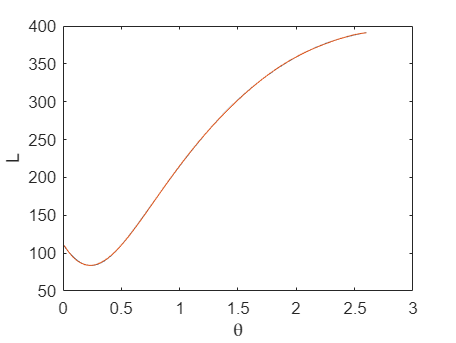

theta_range = 0.01:0.01:2.6;
x_range = shankx_func(theta_range);
y_range = shanky_func(theta_range);
L_range = shankL_func(theta_range);
beta1_range = atan2(x_range,-y_range);

shankL_func_fit = polyfit(theta_range,L_range,8);
shankBeta_func_fit = polyfit(theta_range,beta1_range,8);

plot(theta_range,L_range);hold on;
plot(theta_range,polyval(shankL_func_fit,theta_range));hold off;
xlabel("\theta");ylabel("L");

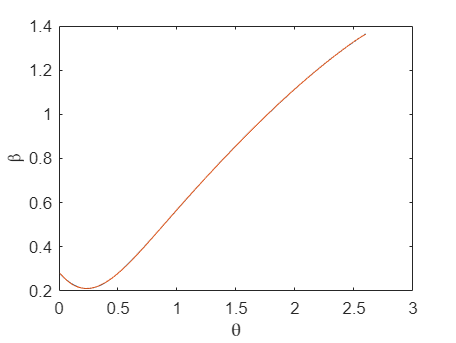

plot(theta_range,beta1_range);hold on;
plot(theta_range,polyval(shankBeta_func_fit,theta_range));hold off;
xlabel("\theta");ylabel("\beta");

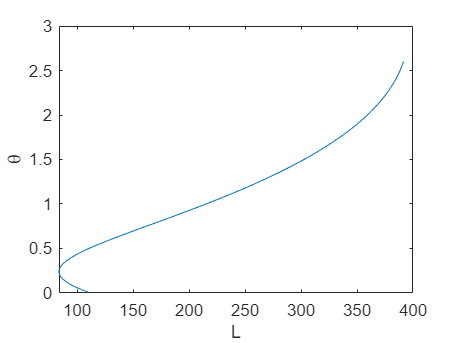

plot(L_range,theta_range);
ylabel("\theta");xlabel("L");


shankL_func_fit

shankL_func_fit =    -7.5624   82.5325 -362.6044  797.4424 -826.7485   84.7238  593.7436 -258.8991  112.6541


shankBeta_func_fit

shankBeta_func_fit =    -0.0173    0.1881   -0.8201    1.7775   -1.7724    0.0278    1.5686   -0.6692    0.2853


% partial_L_theta = diff(shankL_func,theta_2,1)
% partial_beta1_theta = diff(shankBeta_func_fit,theta_2,1)
% 开销太大，直接对多项式求导
partial_L_theta_fit = polyder(shankL_func_fit)

partial_L_theta_fit = 1.0e+03 *

   -0.0605    0.5777   -2.1756    3.9872   -3.3070    0.2542    1.1875   -0.2589


partial_beta1_theta_fit = polyder(shankBeta_func_fit)

partial_beta1_theta_fit =    -0.1386    1.3164   -4.9203    8.8873   -7.0897    0.0833    3.1371   -0.6692


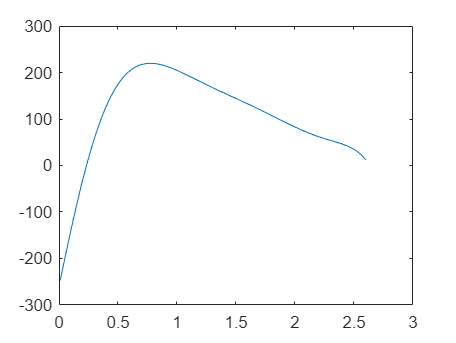



plot(theta_range,polyval(partial_L_theta_fit,theta_range))

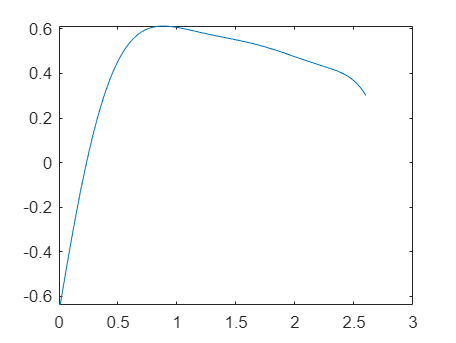

plot(theta_range,polyval(partial_beta1_theta_fit,theta_range))